# **Bouncing Ball System**

close all
clc
system_bb = BouncingBallHybridSystem();

x0 = [1;0];
tspan = [0, 20];
jspan = [0, 30];
sol_bb = system_bb.solve(x0, tspan, jspan)

sol_bb =   HybridSolution with properties:

                    t: [737×1 double]
                    j: [737×1 double]
                    x: [737×2 double]
               f_vals: [737×2 double]
               g_vals: [737×2 double]
               C_vals: [737×1 uint8]
               D_vals: [737×1 uint8]
                   x0: [1 0]
           jump_times: [30×1 double]
          dwell_times: [30×1 double]
        flow_duration: 8.2003
       min_dwell_time: 0.0426
           jump_count: 30
    termination_cause: J_REACHED_END_OF_JSPAN


## Plot flows

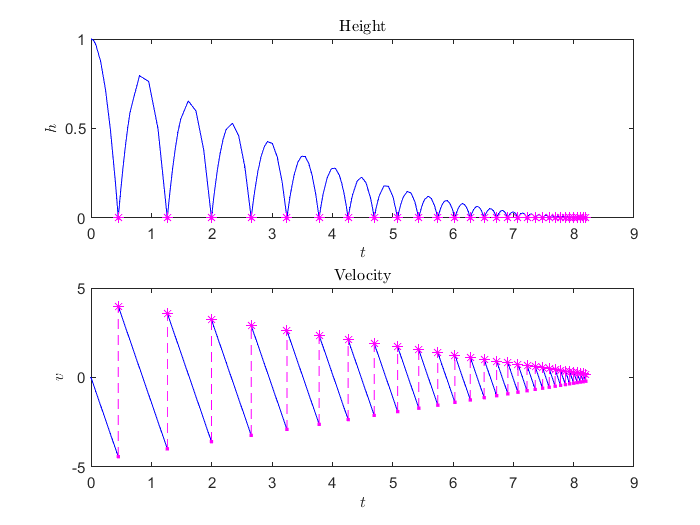

figure(1)
clf
plot_builder_bb = HybridPlotBuilder();
plot_builder_bb.title("Height", "Velocity") ...
    .labels('$h$', '$v$') ...
    .jumpColor('m') ... % Hide jumps
    .plotflows(sol_bb);

## Plot Hybrid Arcs

Plot components 2 and 1--in that order--as hybrid arcs, each in their own subplot. The axes are linked so rotation, zooming, etc. in one subplot is mirrored in all the others plot (the one exception is vertical scaling, which is left independent for each component).

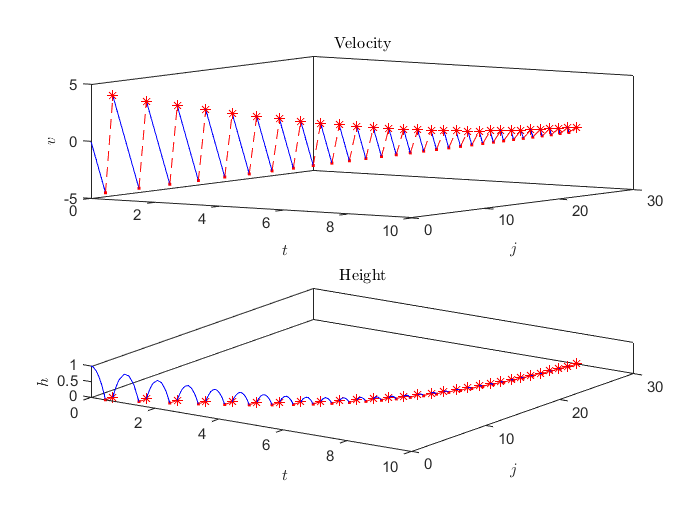

figure(2)
clf
plot_builder_bb.title("Height", "Velocity") ...
    .slice([2, 1]) ... % Switch the order
    .jumpColor('r') ... % Show jumps (they were previously hidden)
    .plotHyrbidArc(sol_bb);

## Plot state

Plot the trajectory of the system in phase space.

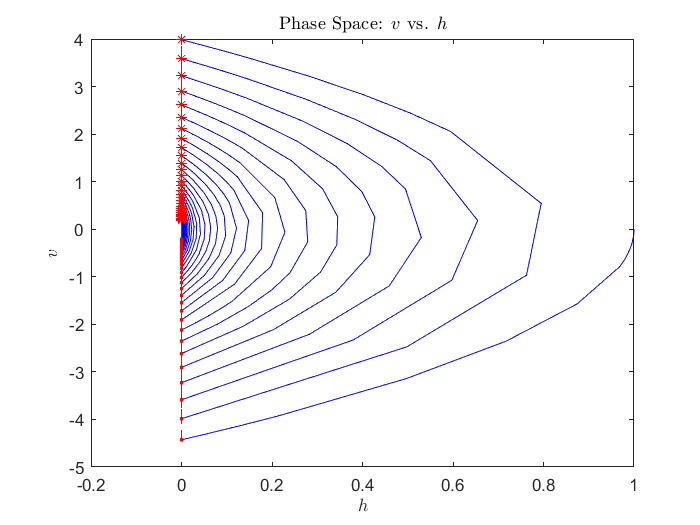

figure(3)
clf
plot_builder_bb = HybridPlotBuilder();
plot_builder_bb.title("Phase Space: $v$ vs. $h$") ...
    .labels('$h$', '$v$') ...
    .plot(sol_bb)

## Plot state with alternative configuration

Plot the trajectory of the system in phase space using a customized plotting configuration. Note that we are using the same object 'plot_builder_bb,' so the values we set for the title and labels are preserved.

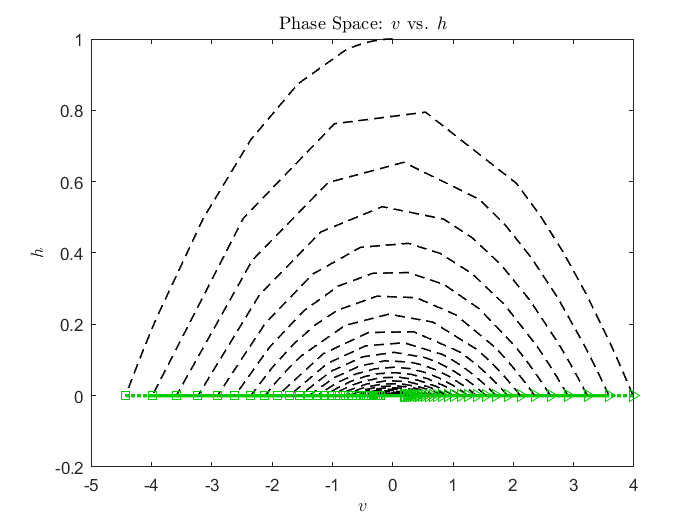

figure(4)
clf
plot_builder_bb ...
    .flowColor("black") ...
    .flowLineStyle("--") ...
    .flowLineWidth(1) ...
    .jumpColor([0, 0.8, 0]) ... % RGB for jump color
    .jumpStartMarker("s") ... % square marker
    .jumpEndMarker(">") ... % triangle
    .jumpLineWidth(2) ...
    .jumpLineStyle(":") ...
    .jumpStartMarkerSize(6) ...
    .jumpEndMarkerSize(6) ...
    .slice([2, 1]) ... % Switch the order of the variables.
    .plot(sol_bb)

## Plot dwell times

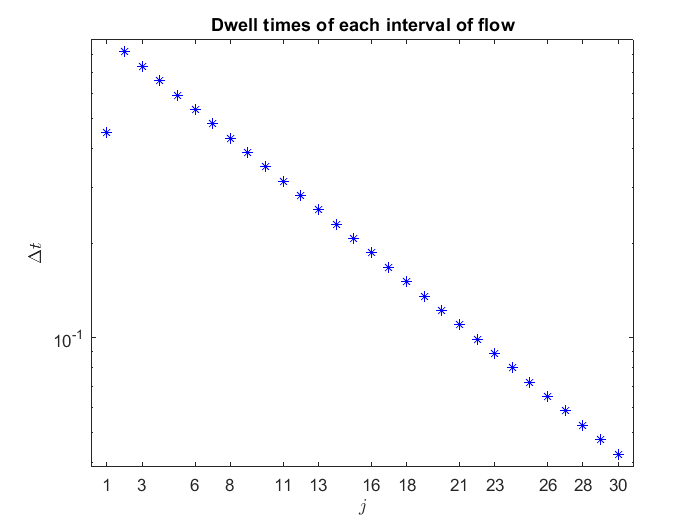

figure(5)
clf
HybridUtils.plotDwellTimes(sol_bb)

## Plot state for a 3D system

Example 6.20 (modified) from the Hybrid Dynamical Systems textbook.

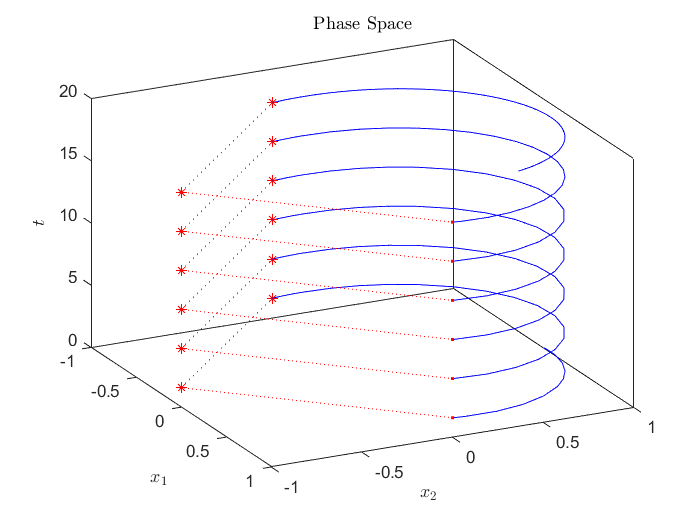

figure(6)
clf
system_3D = Example3DHybridSystem();
sol_3D = system_3D.solve([0; 1; 0], [0, 20], [0, 100]);

HybridPlotBuilder().title("Phase Space") ...
    .labels("$x_1$", "$x_2$", "$t$") ...
    .jumpLineStyle(":") ...
    .plot(sol_3D)
view([63.6 28.2])

## Plotting System Modes

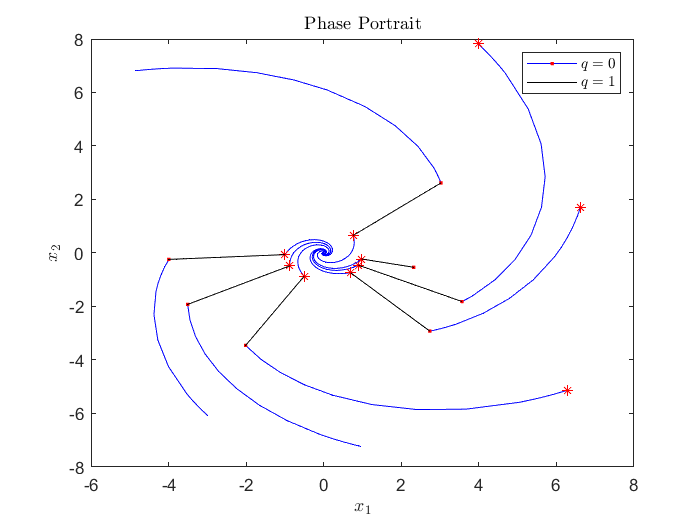

figure(7);
clf
% A 3D system with a continuous variable z \in \reals^2
% and a discrete variable q \in {0, 1}
system_with_modes = ExampleModesHybridSystem();

for i=1:7
    % Create a random initial condition and solve.
    z0 = 20*rand(2, 1) - 10;
    q0 = round(rand());
    sol_modes = system_with_modes.solve([z0; q0], [0, 10], [0, 10], "silent");
    
    q = sol_modes.x(:, 3);
    
    % Plot the [1, 2] components (that is, the first two components) of
    % sol_modes at all time steps where q == 0. 
    builder = HybridPlotBuilder();
    builder.title("Phase Portrait") ...
        .labels("$x_1$", "$x_2$") ...
        .slice([1,2]) ... % Pick which state components to plot
        .filter(q == 0) ... % Only plot points where q is 0.
        .plot(sol_modes)
    hold on
    % Plot in black the solution (still only the [1,2] components) for all time
    % steps where q == 1. 
    builder.flowColor("black") ...
        .jumpColor("none") ...
        .filter(q == 1) ... % Only plot points where q is 1.
        .plot(sol_modes)
end

% Add a legend for each call to builder.plots(). Note that in the loop
% above, a new instance of HybridPlotBuilder is created in each iteration,
% so the legend will only have two entries. 
builder.legend("$q = 0$", "$q = 1$");

## Quick System Definition with *HybridSystemBuilder*

Create a quick in-line definition of a hybrid system. (Not reccomended for long-term use or complex systems.)

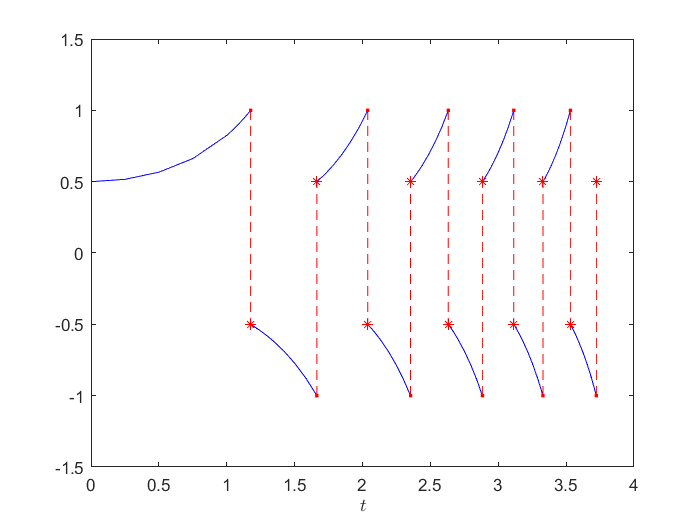

figure(8)
clf
system_EZ = HybridSystemBuilder() ...
            .f(@(x, t) t*x) ... % the function arguments can by (x), (x,t), or (x, t, j).
            .g(@(x) -x/2) ...
            .C(@(x) abs(x) <= 1) ...
            .D(@(x) 1) ...
            .flowPriority() ... % Select flow priority.
            .build();
sol_EZ = system_EZ.solve(0.5, [0, 10], [0, 10]);
plot(sol_EZ) % Note that we can call "plot" on HybridSolutions.

## Run Tests

To run tests, add the 'tests' subfolder to the path. runTests()